structure_stl = "structure.stl";
print_stl = "print.stl";

% How much to translate the structure
ts = [0 0 0];
% How much to rotate the structure
rs = [-90 0 0];

% How much to translate the print
tp = [0 0 50.8-19.04];
% How much to rotate the print
rp = [-90 0 0];

% 1 means all inputs are in degrees
deg = 1;

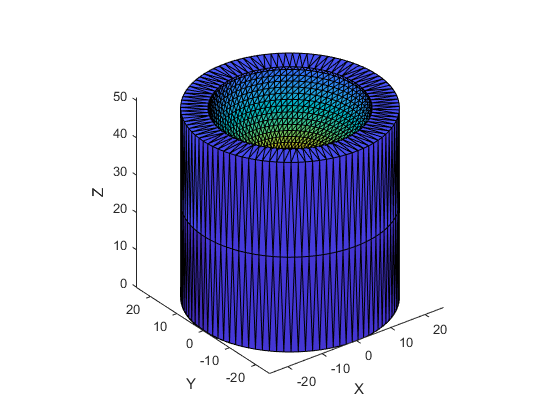

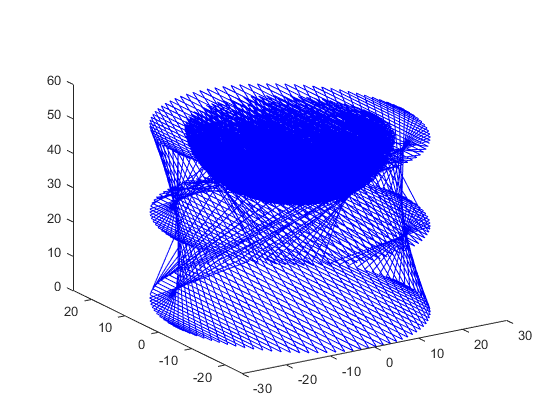

p =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


[Ps,Ts,Ns]=import_stl_fast(structure_stl,1);

[Ps, Ns] = rotate_mesh(Ps,Ns,rs,deg);
Ps = translate_mesh(Ps,ts);

patch('Faces', Ts, 'Vertices', Ps, 'FaceVertexCData', (1:length(Ts(:,1)))', 'FaceColor', 'flat');
view(3)
axis equal
zlabel('Z');xlabel('X');ylabel('Y');

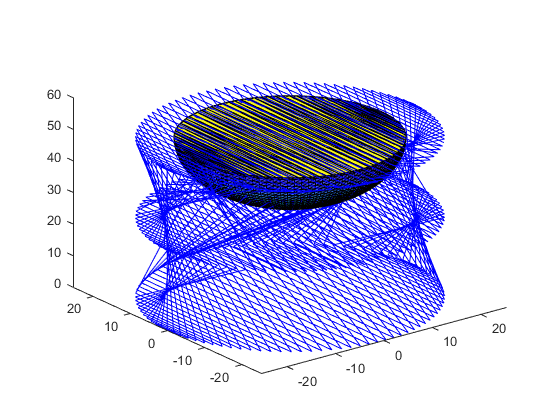

[Pp,Tp,Np]=import_stl_fast(print_stl,1);

[Pp,Np] = rotate_mesh(Pp,Np,rp,deg);
Pp = translate_mesh(Pp,tp);

patch('Faces', Tp, 'Vertices', Pp, 'FaceVertexCData', (1:length(Tp(:,1)))', 'FaceColor', 'flat');